# Задание 6

## Задание 1.

Построить поверхность вращения для заданной на интервале $0\le x\le 3$ линии $y=1+\mathrm{exp}\left(-x\right)\text{ }$ вокруг оси x. Найти площадь и объем.

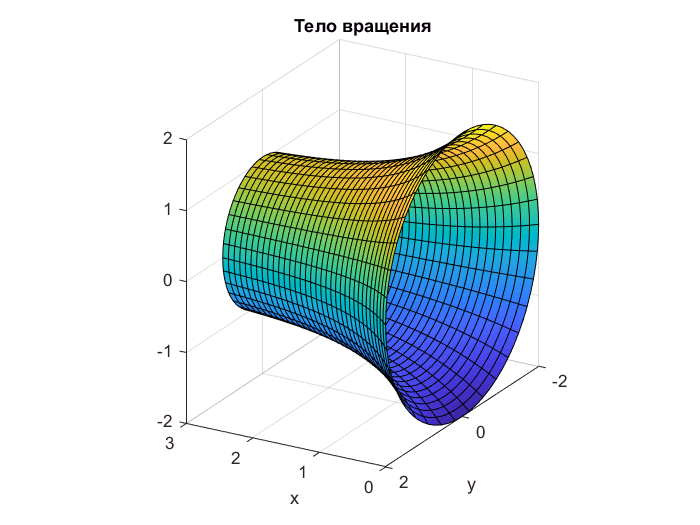

fx = @(x, u) x;
fy = @(x, u) (1 + exp(-x)).*cos(u);
fz = @(x, u) (1 + exp(-x)).*sin(u);
figure('Name', 'Тело вращения', 'NumberTitle', 'off');
fsurf(fx, fy, fz, [0, 3, 0, 2*pi]);
xlabel('x');
ylabel('y');
title('Тело вращения');
axis equal;
view([-150.05 22.31]);

fun = @(x) (1 + exp(-x)).*sqrt(1 + (-exp(-x)).^2);
s = 2 * pi * integral(fun, 0, 3);
fprintf("Площадь поверхности %f\n", s);

Площадь поверхности 27.164432


## Задание 2.

Найти площадь боковой поверхности вращения фигуры, если кривая задана параметрически уравнениями:


$$\begin{array}{l}
x=t-\sin \left(t\right)\\
y=1-\cos \left(t\right)\\
t\in \left\lbrack 0;2\right\rbrack 
\end{array}$$


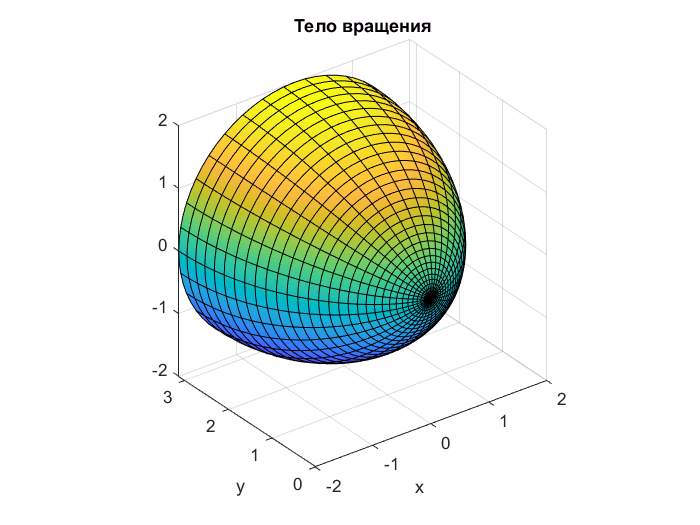

y = @(t, u) t - sin(t);
x = @(t, u) (1 - cos(t)).*cos(u);
z = @(t, u) (1 - cos(t)).*sin(u);
figure('name', 'Тело вращения', 'NumberTitle', 'off');
fsurf(x, y, z, [0, pi, 0, 2*pi])
xlabel('x');
ylabel('y');
axis equal;
title('Тело вращения');
view([-36.92 30.00]);

Найдем производные функций:


$$\begin{array}{l}
y\prime \left(t\right)=1-\mathrm{cos}\left(t\right)\\
x\prime \left(t\right)=\mathrm{sin}\left(t\right)
\end{array}$$


Вычисление площади поверхности:

fun = @(t) (1 - cos(t)).*sqrt((1 - cos(t)).^2 + sin(t).^2);
q = integral(fun, 0, pi);
fprintf("Площадь поверхности тела вращения %f\n", q);

Площадь поверхности тела вращения 5.333333


## Задание 3.

Построить поверхность вращения циклоиды


$$\begin{array}{l}
r=1+\mathrm{cos}\left(\varphi \right)\\
\varphi \in \left\lbrack 0;\pi \right\rbrack 
\end{array}$$


Найти плоскость поверхности вращения.

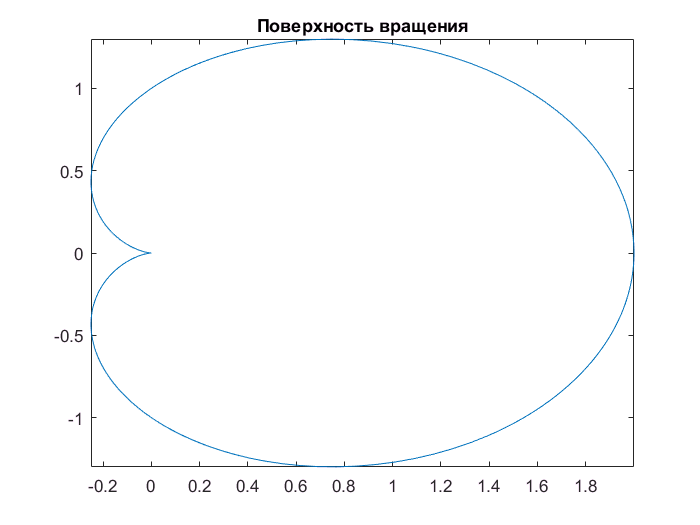

intgr = @(f) (1 + cos(f)).*sin(f).*sqrt(((1 + cos(f)).^2) + (-sin(f).^2));    %Подставил готовые функции
q = integral(intgr, 0, pi);
figure('Name', 'Поверхность вращения', 'NumberTitle', 'off');
fx = @(f) (1 + cos(f)).*cos(f);
fy = @(f) (1 + cos(f)).*sin(f);
fplot(fx, fy);
title('Поверхность вращения');

fprintf("Площадь поверхности тела вращения %f\n", q);

Площадь поверхности тела вращения 1.927527


## Задание 4.

Найти объем конуса, имеющего радиус R = 2м, высоту H = 3м. Построить объемный график такого конуса,как тела вращения.

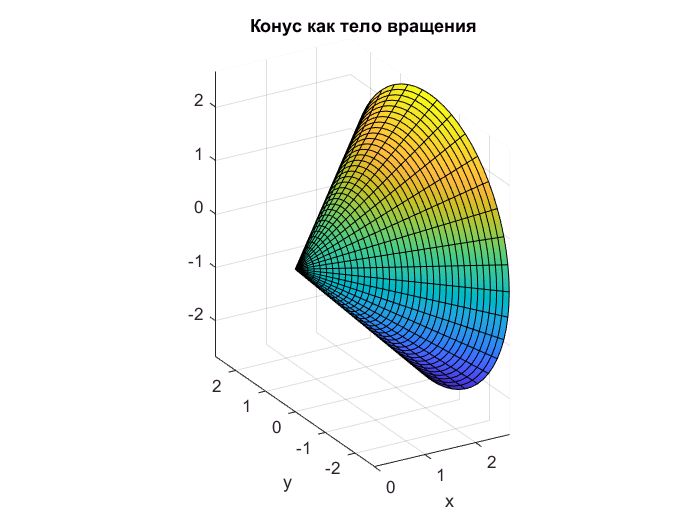

R = 2;
H = 3;
fun = @(u, r) r;
rmax = @(u) R*(1-u);
s = 2*pi*H*integral2(fun, 0, 1, 0, rmax);
x = @(t, u) (-2/3) * t + 2;
y = @(t, u) ((-2/3) * t + 2).*cos(u);
z = @(t, u) ((-2/3) * t + 2).*sin(u);
figure('Name', 'Конус как тело вращения', 'NumberTitle', 'off');
fsurf(x, y, z, [-1, 3, 0, 2*pi])
xlabel('x');
ylabel('y');
title('Конус как тело вращения');
axis equal;
view([-30.55 24.21])

fprintf("Объем конуса %f\n", s);

Объем конуса 12.566371


## Задание 5.

Найти момент инерции данного конуса относительно оси симметрии.

R = 2;
H = 3;
m = 15;
fun = @(u, r) r;
fun1 = @(u, r) r.^2;
rmax = @(u) R*(1-u);
V = 2*pi*H*integral2(fun, 0, 1, 0, rmax);
J = 2*pi*m / V * integral2(fun1, 0, 1, 0, rmax);
fprintf("Момент инерции %f\n", J);

Момент инерции 5.000000
